#   EXAMPLE 1: SINGLE WIND HISTORY

## Buffeting analysis: hypothesis and assumptions:

-  The quasi-steady theory is applied.

-  No modal coupling induced by the wind load is introduced.

-  No structural modal coupling is introduced.

-  Both the along and vertical wind components are taken into account for the buffeting load.

-  The wind direction is assumed normal to the bridge deck

-  The incidence angle of the wind is equal to 0 deg.

-  The frequency-domain approach is used.

In the present case, the matrices of buffeting load $\textbf{A}$and the cross-spectrum matrix of wind turbulence  $\textbf{S}$ are defined as


$$\textbf{A} = \frac{1}{2} \rho \overline{u} B$$

$$\pmatrix{
2\frac{D}{B} C_{D}\cdot \chi_{ux}  & \frac{D}{B}C_{D}'-C_{L}\cdot \chi_{wx}\cr
2C_{L}\cdot \chi_{uz}  & C_{L}'+\frac{D}{B}C_{D}\cdot \chi_{wz}\cr
2BC_{M}\cdot \chi_{u\theta}  & BC_{M}'\cdot \chi_{w\theta}\cr
}
$$



$$\textbf{S}(y,f) = $$

$$\pmatrix{
\sqrt{S_{u} \cdot S^{\top}_{u}} \gamma_{uu}  &  \sqrt{Co_{uw} \cdot Co^{\top}_{uw}} \gamma_{uw} \cr
\sqrt{Co_{uw} \cdot Co^{\top}_{uw}} \gamma_{uw}  & \sqrt{S_{w} \cdot S^{\top}_{w}} \gamma_{ww} \cr
}
$$


where $\gamma_{uu}$ and $\gamma_{ww}$ are the co-coherence of the along-wind and vertical velocity components, respectively.

The cross-spectrum matrix of wind load at each "node" is


$$\textbf{S}_{qq}(y,f) =  \textbf{A} \textbf{S}(y,f) \textbf{A}^{\top}$$


The modal wind load is computed as


$$\textbf{S}_{QQ}(f)  = 
\int\limits_{0}^{L}
\int\limits_{0}^{L}
\Phi(y_{1})\textbf{S}_{qq}(y_{1},y_{2},f)\Phi(y_{2})d y_{1}d y_{2} $$


The power spectral density of the bridge response at abscissa $y$ of the bridge is:


$$\textbf{S}_r(f,y)  = \left[\Phi(y)  \textbf{H}(f)\right]  \textbf{S}_{QQ}(f) \left[  \Phi(y) \textbf{H}(f) \right]^{\top}$$


where $\textbf{H}(f)$ is the mechanical admittance of the system modified by the modal aerodynamic damping and stiffness.

The standard deviation of the bridge displacement $\sigma_{r}(y)$ at abscissa $y$ is:


$$\sigma_r(y) = $$

$$\sqrt{\int\limits_{0}^{\infty} \textbf{S}_{r}(f,y)  d f }

$$


where


$$\sigma_r (y) = $$
 
$$\pmatrix{
\sigma_{r_x}(y) \cr \sigma_{r_z}(y) \cr \sigma_{\theta}(y)
}$$


## Bridge modelling

#### Bridge modal properties

phi and wn are the mode shapes and eigen frequencies of the main span, respectively.

clearvars;close all;clc;
load('bridgeModalProperties.mat','wn','phi')

% Lateral mode shapes:
phiH = squeeze(phi(1,:,:));
% Vertical mode shapes:
phiV = squeeze(phi(2,:,:));
% Torsional mode shapes:
phiT = squeeze(phi(3,:,:));

% Lateral eigen frequencies:
wnH = squeeze(wn(1,:));
% Vertical mode shapes:
wnV = squeeze(wn(2,:));
% Torsional mode shapes:
wnT = squeeze(wn(3,:));

[Nmodes,Nyy]=size(phiH); % Nyy: number of "nodes"

% Structural modal damping ratio for the  Bridge deck: it is here taken as 0.5 % for every mode
Bridge.zetaStruct = 5e-3.*ones(1,Nmodes);

#### Bridge structural properties

The mechanical properties of the single-span suspension bridge are written below.

Bridge.B = 12.3 ; % width of the bridge deck (m)
Bridge.D = 2.76 ; % height of the bridge deck (m)
Bridge.L = 446 ; % Length of the main span (m)
Bridge.x = linspace(0,1,Nyy) ; % normalized bridge main span
Bridge.m = 5350 ; % lineic mass of girder (kg/m)
Bridge.mc = 408 ; % lineic mass of cable (kg/m)
Bridge.m_theta = 82430; % torsional stifness (kg.m^2/m)
Bridge.k = 1/4; % bridge constant . cf aerodynamic of streamlined bridge
% aerodynamic coefficient (quasi steady terms)
Bridge.Cd = 1;% drag coefficient
Bridge.dCd = 0;% first derivative of drag coefficient
Bridge.Cl = 0.1;% lift coefficient
Bridge.dCl = 3;% first derivative of lift coefficient
Bridge.Cm = 0.02;% pitching moment coefficient
Bridge.dCm = 1.12;% first derivative of pitching moment coefficient


#### Selection of position where the response is computed

The response is here computed at 1/3 of the bridge. Note that x is the normalized span length ranging from  0 to 1

[~,indPos] = min(abs(Bridge.x-1/3)); % get the indice closest to the 1/3

## Duration and sampling frequency definition

tmax = 600; % based on 600 seconds of records = 10 min
fs = 10; % sampling frequency of 30 Hz is chosen
fmin = 1/tmax; % minimal frequency recorded
fmax = fs/2; % max frequency recorded
Nfreq = 600;
f = logspace(log10(fmin),log10(fmax),Nfreq);

## Wind turbulence characteristics

%% Semi empirical wind spectrum (Von karman)
clear Wind
Wind.U = 10; % mean wind speed normal to the bridge deck
Wind.Cuy = 7; % decay coefficient for co-coherence for u-component along bridge span
Wind.Cwy = 6; % decay coefficient for co-coherence for w-component along bridge span
Wind.f = f;

Lu = 100;
Lw = Lu/10;
stdU = 0.15*Wind.U;
stdW = 0.55*stdU;
[Su] = VonKarmanSpectrum(f,Wind.U,stdU,Lu,'u');
[Sw] = VonKarmanSpectrum(f,Wind.U,stdW,Lw,'w');
% Storage of the data into the structure variableWind .
Wind.Su = Su;
Wind.Sw = Sw;

%% Overview of the fundamental inputs
fprintf(' The varable Wind is : \n\n')

 The varable Wind is : 



disp(Wind)

      U: 10
    Cuy: 7
    Cwy: 6
      f: [1×600 double]
     Su: [1×600 double]
     Sw: [1×600 double]



fprintf(' The varable Bridge is : \n\n')

 The varable Bridge is : 



disp(Bridge)

    zetaStruct: [0.0050 0.0050 0.0050 0.0050]
             B: 12.3000
             D: 2.7600
             L: 446
             x: [1×30 double]
             m: 5350
            mc: 408
       m_theta: 82430
             k: 0.2500
            Cd: 1
           dCd: 0
            Cl: 0.1000
           dCl: 3
            Cm: 0.0200
           dCm: 1.1200



## Computation of the buffeting response of the bridge

#### Lateral bridge response

Bridge.DOF = 'lateral';
Bridge.wn = wnH;  % lateral eigen frequencies  (rad/s)
Bridge.phi = phiH; % lateral mode shapes
[Srx] = dynaRespFD3(Bridge,Wind,indPos); % compute PSD of response

#### Vertical bridge response

Bridge.DOF = 'vertical';
Bridge.wn = wnV; % vertical eigen frequencies  (rad/s)
Bridge.phi = phiV; % vertical mode shapes
[Srz] = dynaRespFD3(Bridge,Wind,indPos);

#### Torsional bridge response

Bridge.DOF = 'torsional';
Bridge.wn = wnT; % torsional eigen frequencies  (rad/s)
Bridge.phi = phiT; % torsional mode shapes
[Srt] = dynaRespFD3(Bridge,Wind,indPos);

## Visualization of the PSDs of the bridge displacement response

#### Lateral bridge response

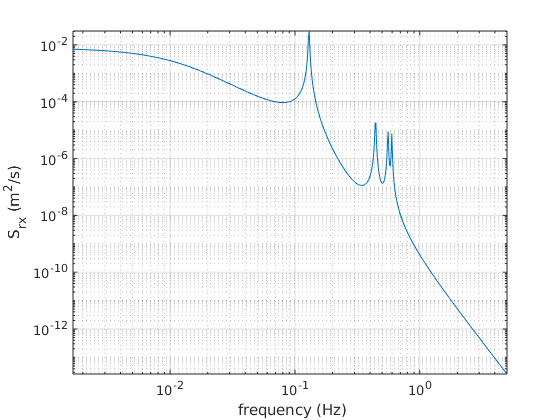

figure
loglog(f,Srx);
xlabel(' frequency (Hz)');
ylabel('S_{rx} (m^2/s)');
axis tight
grid on

#### Vertical bridge response

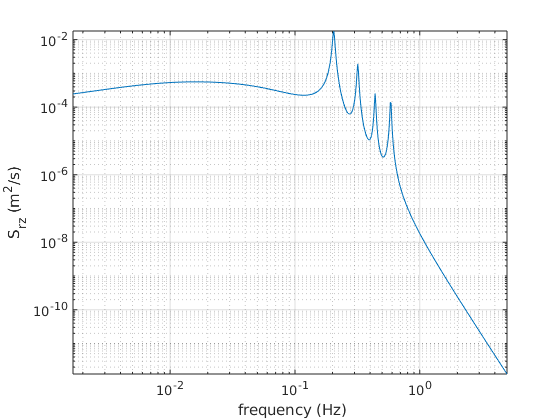

figure
loglog(f,Srz);
xlabel(' frequency (Hz)');
ylabel('S_{rz} (m^2/s)');
axis tight
grid on

#### Torsional bridge response

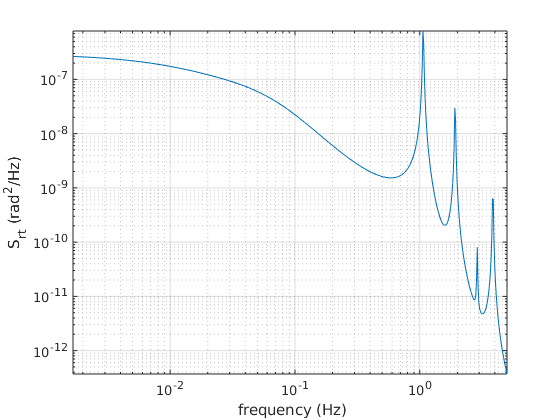

figure
loglog(f,Srt);
xlabel(' frequency (Hz)');
ylabel('S_{rt} (rad^2/Hz)');
axis tight
grid on

## Sensitivity study (vertical bridge displacement response)

#### Use of difference coherence model (Davenport vs ESDU)

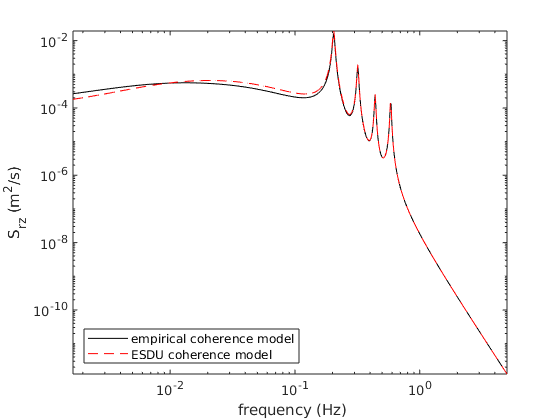

Bridge.DOF = 'vertical';
Bridge.wn = wnV;
Bridge.phi = phiV;
Wind.Cuy = 7 ; % large decay coeff
Wind.Cwy = 7; % large decay coeff

[Srz1] = dynaRespFD3(Bridge,Wind,indPos);
[Srz2] = dynaRespFD3(Bridge,Wind,indPos,'cohType','ESDU');

figure
plot(f,Srz1,'k',f,Srz2,'r--');
legend('empirical coherence model','ESDU coherence model','location','SouthWest')
set(gca,'Xscale','log');
set(gca,'Yscale','log');
xlabel(' frequency (Hz)');
ylabel('S_{rz} (m^2/s)');
axis tight

#### Influence of the mean wind speed on the buffeting response

A larger mean wind speed increases the aerodynamic damping of the structure

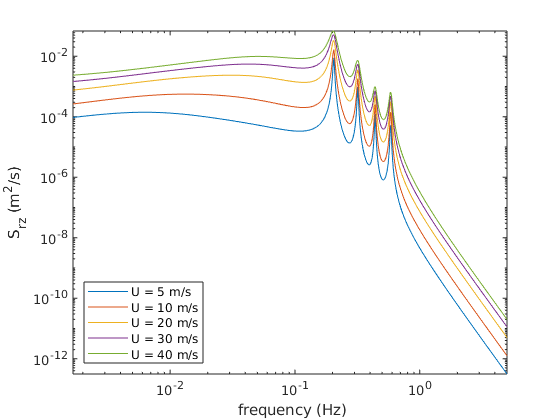

myU = [5,10,20,30,40]; % different mean wind speed

Srz_test = zeros(numel(myU),Nfreq);
for ii=1:numel(myU)
    Wind.U = myU(ii);
    [Srz_test(ii,:)] = dynaRespFD3(Bridge,Wind,indPos);
end
Wind.U = 10;

figure
plot(f,Srz_test);
legend('U = 5 m/s','U = 10 m/s','U = 20 m/s','U = 30 m/s','U = 40 m/s',...
    'location','SouthWest')
set(gca,'Xscale','log');
set(gca,'Yscale','log');
xlabel(' frequency (Hz)');
ylabel('S_{rz} (m^2/s)');
axis tight

#### Influence of the structural damping ratios on the buffeting response

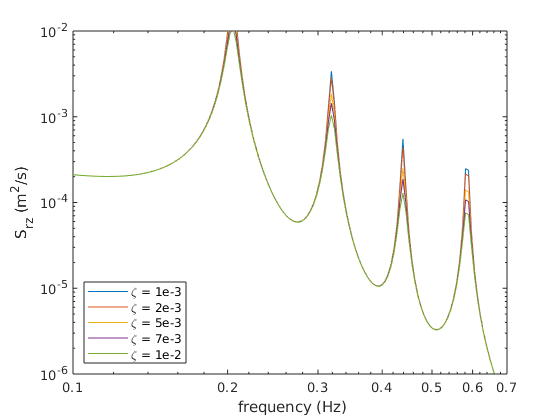

Bridge.DOF = 'vertical';
Bridge.wn = wn(2,:);
Bridge.phi = squeeze(phi(2,:,:));
Wind.Cuy = 7 ;
Wind.Cwy = 7;

myZeta = [1,2,5,7,10].*1e-3; % Different damping ratios

Srz_test = zeros(numel(myZeta),Nfreq);
for ii=1:numel(myZeta)
    Bridge.zetaStruct = myZeta(ii).*ones(1,Nmodes);
    [Srz_test(ii,:)] = dynaRespFD3(Bridge,Wind,indPos);
end

figure
plot(f,Srz_test);
legend('\zeta = 1e-3','\zeta = 2e-3','\zeta = 5e-3','\zeta = 7e-3',...
    '\zeta = 1e-2','location','SouthWest')
set(gca,'Xscale','log');
set(gca,'Yscale','log');
xlabel(' frequency (Hz)');
ylabel('S_{rz} (m^2/s)');
xlim([0.1,0.7])
ylim([1e-6,1e-2])

#### Influence of the turbulence intensity on the buffeting response

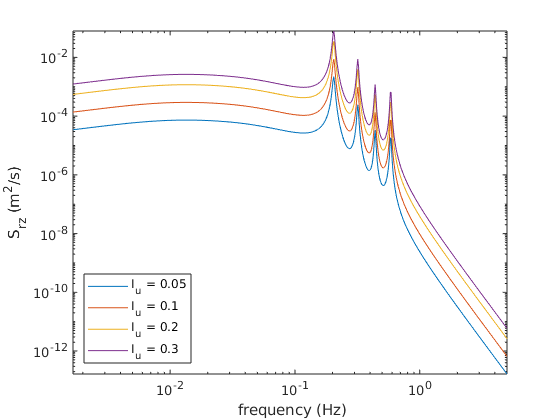

Bridge.zetaStruct = 5e-3.*ones(1,Nmodes);
myIu = [0.05,0.1,0.2,0.3];

Srz_test = zeros(numel(myIu),Nfreq);
for ii=1:numel(myIu)
    stdU = myIu(ii)*Wind.U;
    stdW = 0.6*stdU;
    Su = VonKarmanSpectrum(f,Wind.U,stdU,Lu,'u');
    Sw = VonKarmanSpectrum(f,Wind.U,stdW,Lw,'w');
    Wind.Su = Su;
    Wind.Sw = Sw;
    [Srz_test(ii,:)] = dynaRespFD3(Bridge,Wind,indPos);
end

figure
plot(f,Srz_test);
legend('I_u = 0.05','I_u = 0.1','I_u = 0.2','I_u = 0.3',...
    'location','SouthWest')
set(gca,'Xscale','log');
set(gca,'Yscale','log');
xlabel(' frequency (Hz)');
ylabel('S_{rz} (m^2/s)');
axis tight


Wind.Iu = 0.1; % TI for u-component
Wind.Iw = Wind.Iu*0.6; % TI for w-component


#### Influence of the integral length scale on the buffeting response

This section is only relevant if the von Karman velocity spectra are used.

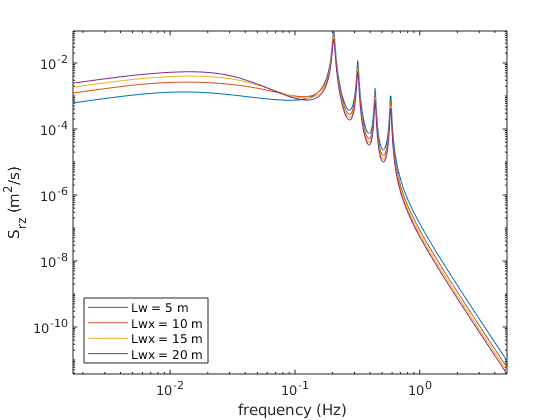


Lu = [50,100,150,200]; % Different values are used
Srz = zeros(numel(Lu),Nfreq);
for ii=1:numel(Lu)
    Su = VonKarmanSpectrum(f,Wind.U,stdU,Lu(ii),'u');
    Sw = VonKarmanSpectrum(f,Wind.U,stdW,0.1*Lu(ii),'w'); % Lw = 0.1*Lu
    Wind.Su = Su;
    Wind.Sw = Sw;
    [Srz(ii,:)] = dynaRespFD3(Bridge,Wind,indPos);
end

figure
plot(f,Srz);
legend('Lw = 5 m','Lwx = 10 m','Lwx = 15 m','Lwx = 20 m',...
    'location','SouthWest')
set(gca,'Xscale','log');
set(gca,'Yscale','log');
xlabel(' frequency (Hz)');
ylabel('S_{rz} (m^2/s)');
axis tight